clear;
close all;
clc;

1) Load data

path='data\SRAS\Task 2\Task_2_Ti_demo.mat';
load(path);

2) Get the readings from data from 2.1 - 2.4

noY=length(y);
dy=abs(y(2)-y(1));
noX=length(x);
dx=abs(x(2)-x(1));
vMax=max(max(vel));
vMin=min(min(vel));

3) SARS imaging

num_of_points = noY*noX;
scanspeed = 1000; % typically ~1000 pts/s, got from paper [1], section 3.
total_scan_time=num_of_points/scanspeed/60/60; % hour

display(total_scan_time)

total_scan_time = 0.2467

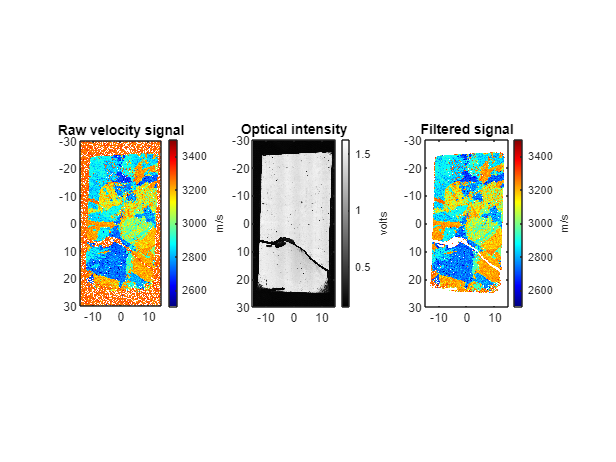


colors=[1,1,1;jet(300)];

figure
ax(1)=subplot(1,3,1);
imagesc(x,y,vel)
axis equal;
axis tight;
caxis([vMin,vMax])
h=colorbar;
colormap(ax(1),colors)
title('Raw velocity signal')
h.Label.String='m/s';

ax(2)=subplot(1,3,2);
imagesc(x,y,opt)
axis equal;
axis tight;
h=colorbar;
colormap(ax(2),gray)
h.Label.String='volts';
title('Optical intensity')

% masking the unwanted data (artefacts)
threshold=0.45; % threshold of abandoning data, gained by reading off the intensity chart
mask = opt;
mask(opt<threshold) = 0;
mask(opt>=threshold) = 1;

vel_filtered=vel.*mask;

ax(3)=subplot(1,3,3);
imagesc(x,y,vel_filtered)
axis equal;
axis tight;
h=colorbar;
colormap(ax(3),colors)
caxis([vMin,vMax])
title('Filtered signal')
h.Label.String='m/s';